# Resolución de Casos 02

- Sección: 5

- N° de grupo: 7

- Integrante 1 (líder): Mariela del Carmen Ocampo Lecca

- Integrante 2:

- Integrante 3:

- Integrante 4:

- Integrante 5:

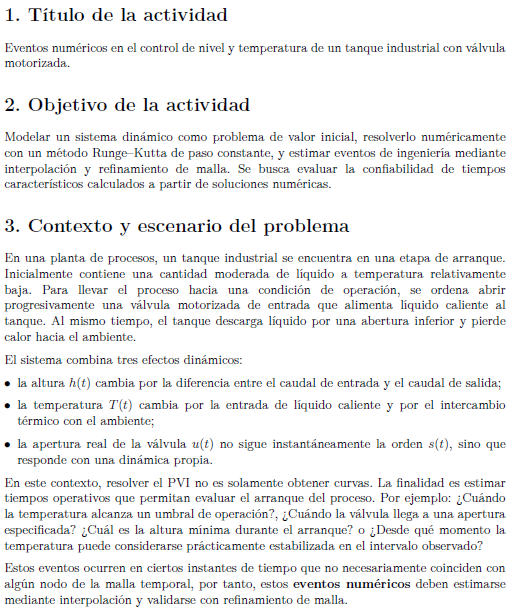

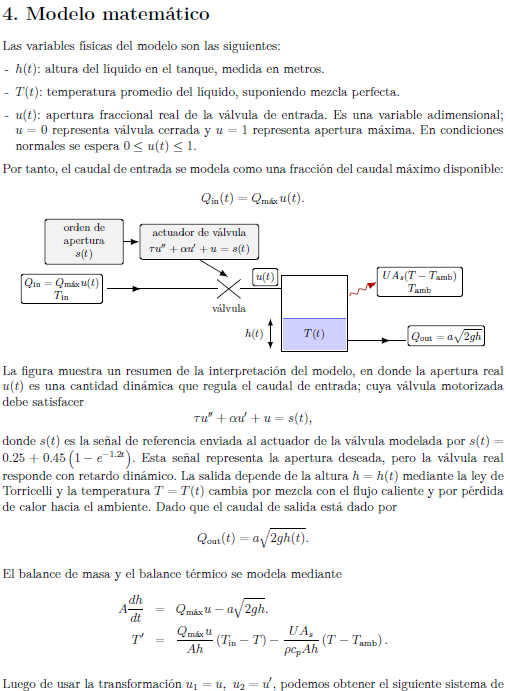

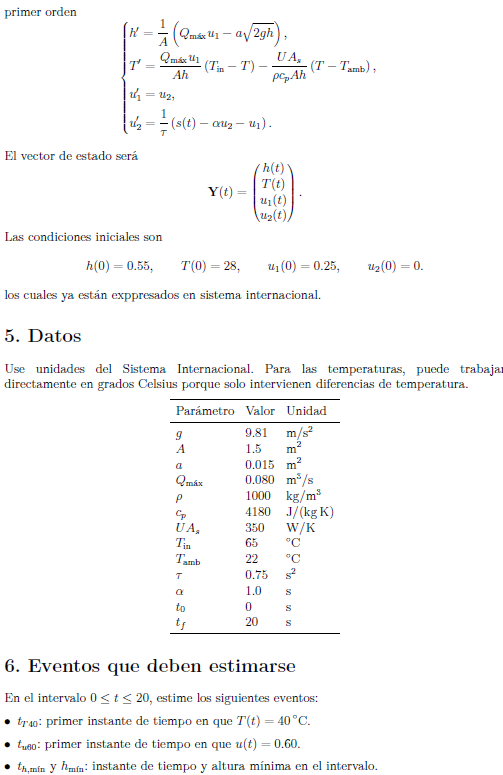

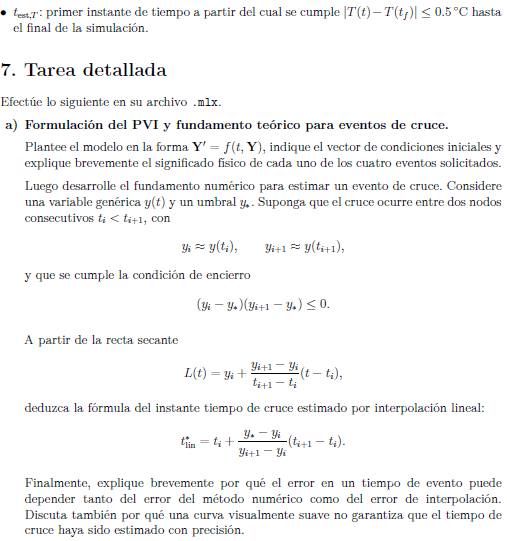

% Definimos los parámetros del sistema, el vector de condiciones iniciales y la señal de referencia de la válvula
g = 9.81;
A = 1.5;
a = 0.015;
Qmax = 0.080;
rho = 1000;
cp = 4180;
UAs = 350;
Tin = 65;
Tamb = 22;
tau = 0.75;
alpha = 1.0;
t0 = 0;
tf = 20;

Y0 = [0.55; 28; 0.25; 0];

s = @(t) 0.25 + 0.45 * (1 - exp(-1.2 * t));

% Definimos la función del PVI en la forma Y' = f(t, Y)
% Y(1) = h, Y(2) = T, Y(3) = u1, Y(4) = u2
f_pvi = @(t, Y) [ ...
    (1/A) * (Qmax * Y(3) - a * sqrt(2 * g * Y(1))); ...
    (Qmax * Y(3) / (A * Y(1))) * (Tin - Y(2)) - (UAs / (rho * cp * A * Y(1))) * (Y(2) - Tamb); ...
    Y(4); ...
    (1/tau) * (s(t) - alpha * Y(4) - Y(3)) ...
    ];


% Significado físico de cada uno de los 4 eventos
%
% Evento 1: Es el tiempo transcurrido hasta que el líquido alcanza los 40°C. 
% Mide la velocidad de calentamiento inicial.
%
% Evento 2: Es el tiempo en el que la apertura real de la válvula llega al 60%.
% Evalúa el retardo del actuador mecánico respecto a la orden s(t).
%
% Evento 3: Es el instante y el valor del nivel más bajo del tanque.
% Indica el punto crítico de vaciado transitorio antes de que el caudal de entrada supere al de salida.
%
% Evento 4: Es el tiempo en el que la temperatura se estabiliza dentro de una banda de tolerancia de +-0.5°C respecto al valor final.
% Indica que el proceso térmico entró en estado estacionario práctico.

**Fundamento numérico para estimar un evento de cruce**:

Queremos hallar el tiempo de cruce (t_lin*) donde la recta secante L(t) intercepta exactamente el umbral deseado (y_*). Es decir, L(t_lin*) = y_*

Partimos de la ecuación dada: y_* = y_i + ((y_{i+1} - y_i) / (t_{i+1} - t_i)) * (t_lin* - t_i)

Pasamos y_i restando al lado izquierdo: y_* - y_i = ((y_{i+1} - y_i) / (t_{i+1} - t_i)) * (t_lin* - t_i)

Multiplicamos ambos lados por el inverso de la pendiente: ((y_* - y_i) / (y_{i+1} - y_i)) * (t_{i+1} - t_i) = t_lin* - t_i

Despejamos t_lin* pasando t_i sumando al lado derecho: t_lin* = t_i + ((y_* - y_i) / (y_{i+1} - y_i)) * (t_{i+1} - t_i)

**¿Por qué el error en un tiempo de evento depende tanto del método numérico como del error de interpolación?**

Porque los puntos que usamos para interpolar ya vienen con error desde el método Runge-Kutta. Si a eso le sumamos que estamos aproximando una curva real uniendo los puntos con una línea recta, el resultado final arrastra ambos fallos de precisión.

**¿Por qué una curva visualmente suave no garantiza que el tiempo de cruce haya sido estimado con precisión?**

Porque la suavidad en la gráfica es solo un efecto visual que depende del zoom o de la pantalla. Si el paso de tiempo en la simulación es muy grande, la recta que tira la interpolación puede ignorar el verdadero comportamiento de la curva a nivel decimal. Por eso hay que verificar con refinamiento de malla.

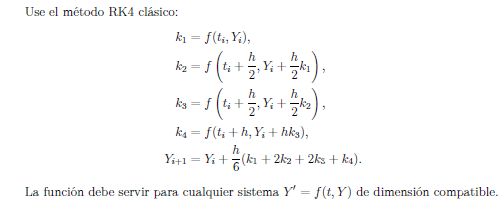

%realice aqui su codigo



%Escriba aqui su explicación

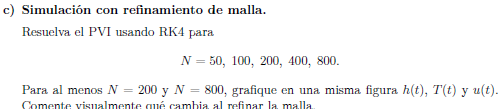

%realice aqui su codigo




%Escriba aqui su explicación

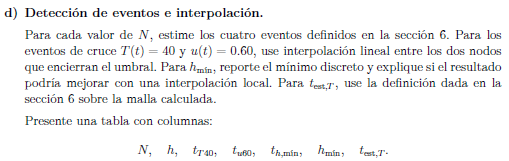

%realice aqui su codigo



%Escriba aqui su explicación

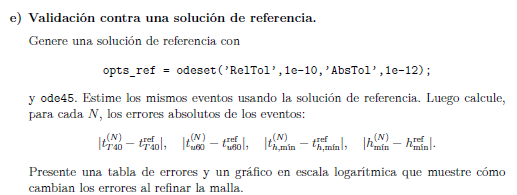

%realice aqui su codigo




%Escriba aqui su explicación

      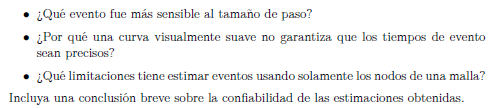

%realice aqui su codigo




%Escriba aqui su explicación